# Matching Spectrum with Spectral Measures on TI and TE dataset with MATLAB

This demo project demonstrated how to compute several spectral matching measures for a hyperspectral image dataset using MATLAB.

## 1. Download the Dataset from Github and Loading the Dataset

Downloads the dataset by cloning the tite GitHub repository to the local environment. The dataset is stored in a folder named tite. Then, we can load the variables from the tite_reflectance.mat file into the MATLAB environment.

% Download Dataset
if ~exist("./tite/tite_reflectance.mat")
    gitclone("https://github.com/Brunoxue/tite.git");
end

% Load Dataset
load("tite/tite_reflectance.mat");
hsi=double(TI2);
M=double(minerals);

## 2. Visualization of TI2 Hyperspectral Imagery

The block sets up a tiled layout with two panels: one for visualizing  the 100th band of the hyperspectral image (hsi) using imagesc, and another for plotting spectral intensity across bands.

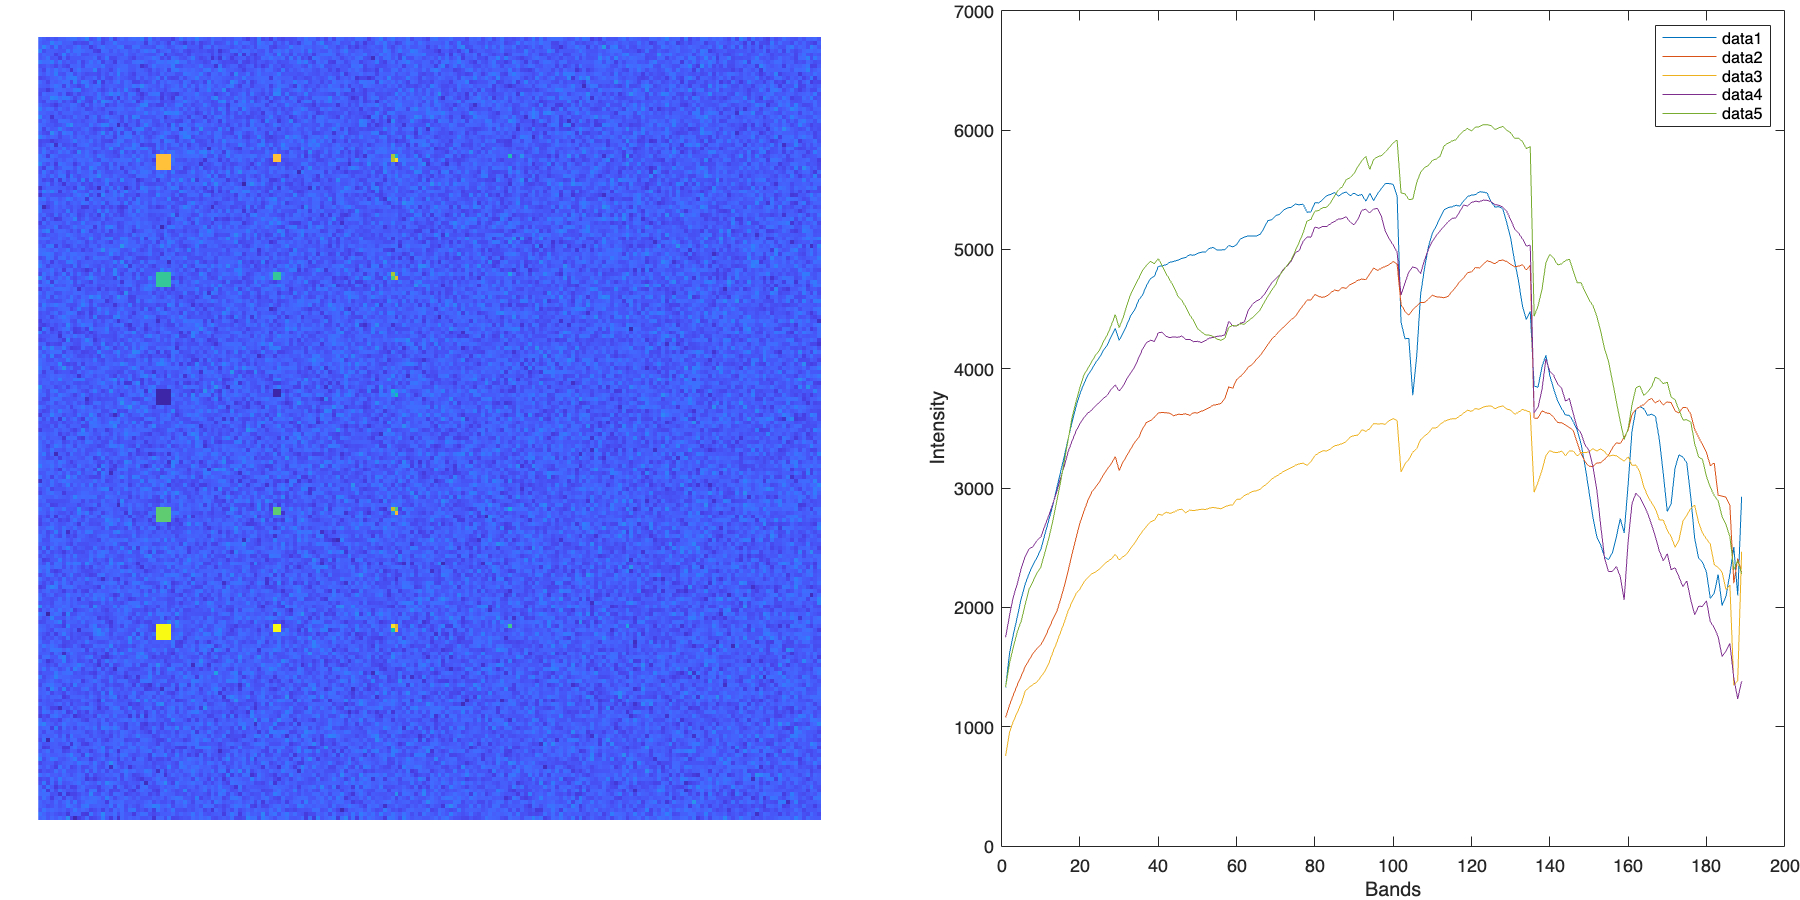

figure("Units","pixels","Position",[1,1,1000,500]);
tiledlayout(1,2,"Padding","tight");

% First tile: Visualize the 100th band of the hyperspectral image
nexttile,
imagesc(hsi(:,:,100)),axis off,axis image;

% Second tile: Plot the spectral intensity across bands
nexttile,plot(M);
legend;
xlabel("Bands");
ylabel("Intensity");

## 3. Euclidean Distance (ED)

Euclidean Distance (ED) is a simple method to measure the distance between two spectra by calculating the distance in the Euclidean space. This block demostrate the results of ED between the hyperspectral image HSI and five different reference spectra.

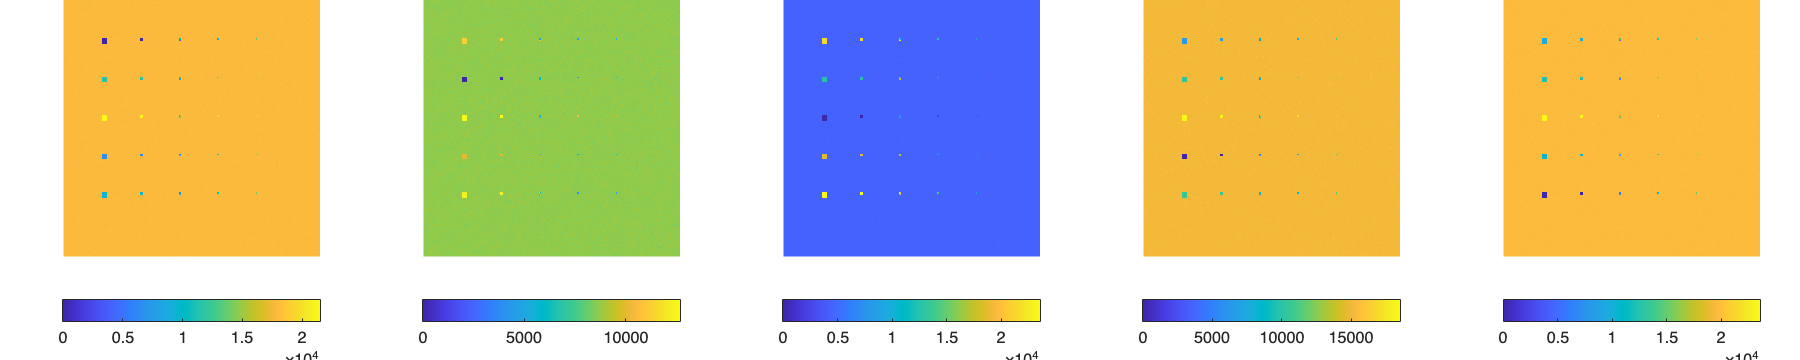

% ED
figure("Units","pixels","Position",[1,1,1000,200]);
tiledlayout(1,5,"TileSpacing","tight","Padding","tight");
for idx = 1:5
    resultsED=ED(hsi,M(:,idx));
    nexttile,imagesc(resultsED),axis off,axis image;
    colorbar southoutside;
end

## 4. Spectral Angle Mapper (SAM)

Spectral Angle Mapper (SAM) is an angular-based similarity measure between the spectra, where the angle between the spectral vectors is computed. Smaller angles indicate higher similarity.

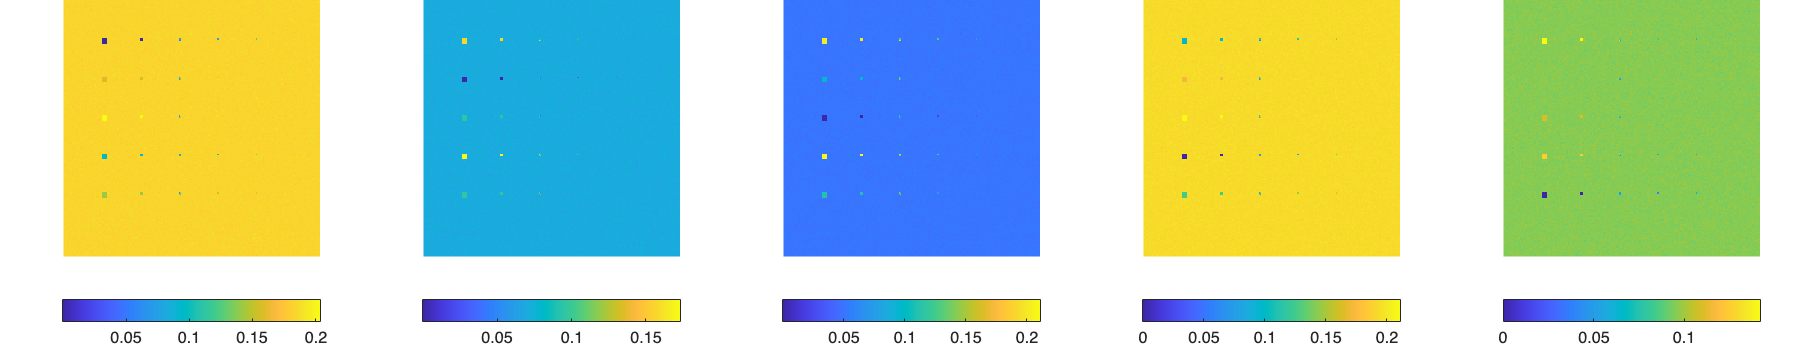

% SAM
figure("Units","pixels","Position",[1,1,1000,200]);
tiledlayout(1,5,"TileSpacing","tight","Padding","tight");
for idx = 1:5
    resultsSAM=SAM(hsi,M(:,idx));
    nexttile,imagesc(resultsSAM),axis off,axis image;
    colorbar southoutside;
end

## 5. Spectral Information Divergence (SID)

SID measures the divergence between two probability distributions of spectral signatures. It’s based on the information-theoretic concept and detects differences in spectral signatures’ information content.

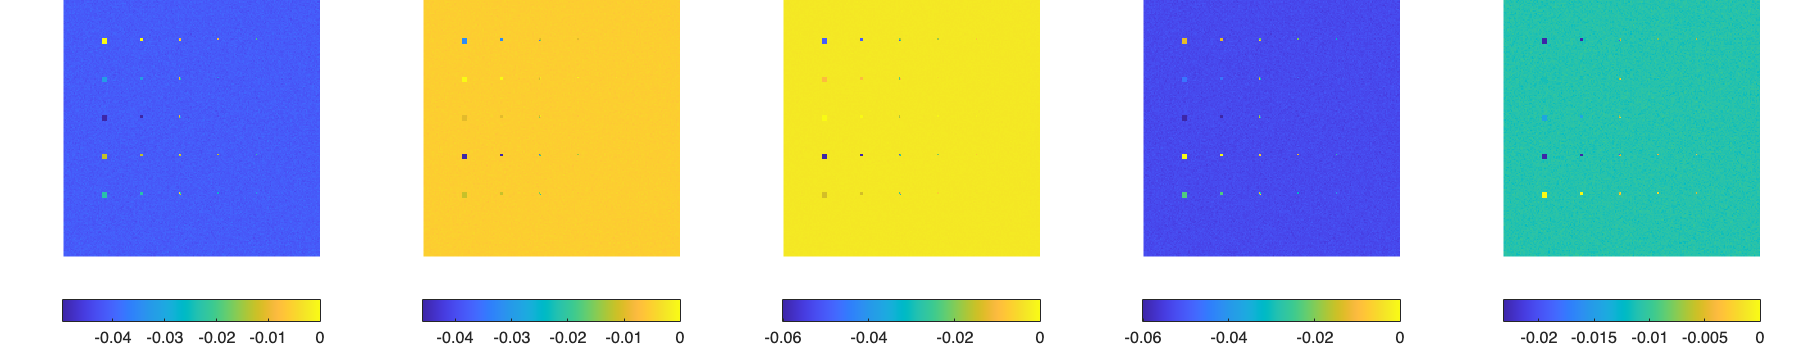

% SID
figure("Units","pixels","Position",[1,1,1000,200]);
tiledlayout(1,5,"TileSpacing","tight","Padding","tight");
for idx = 1:5
    resultsSID=SID(hsi,M(:,idx));
    nexttile,imagesc(resultsSID),axis off,axis image;
    colorbar southoutside;
end

## 6. Spectral Information Divergence-Spectral Angle Mapper (SID-SAM)

This section combines the SID and SAM measures by multiplying the SID values with the tangent of the SAM angle.

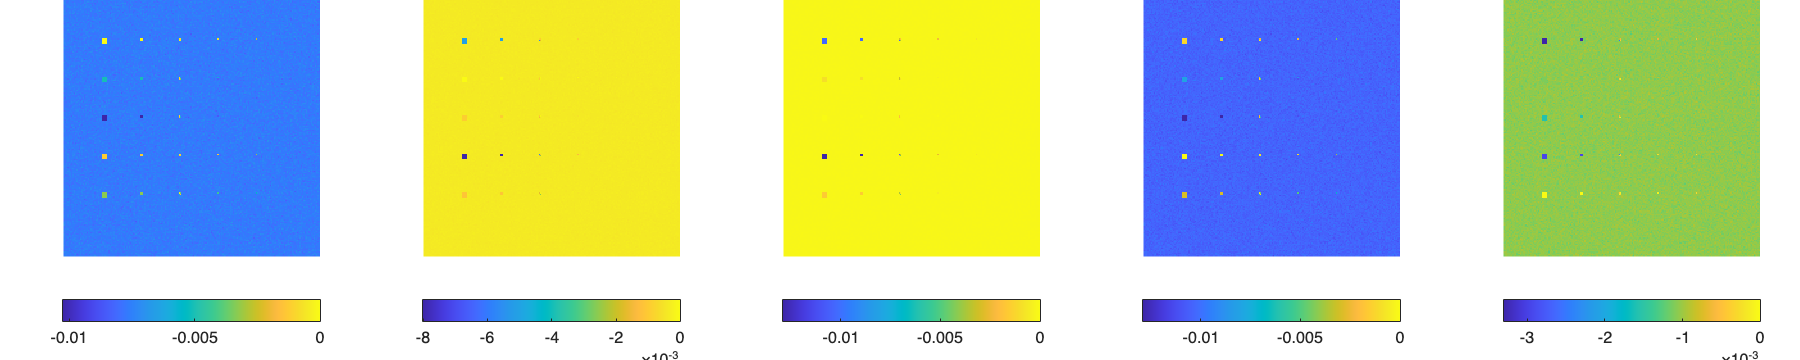

% SID-SAM
figure("Units","pixels","Position",[1,1,1000,200]);
tiledlayout(1,5,"TileSpacing","tight","Padding","tight");
for idx = 1:5
    resultsSIDSAM=SID_SAM(hsi,M(:,idx));
    nexttile,imagesc(resultsSIDSAM),axis off,axis image;
    colorbar southoutside;
end

## 7. Orthogonal Projection Divergence (OPD)

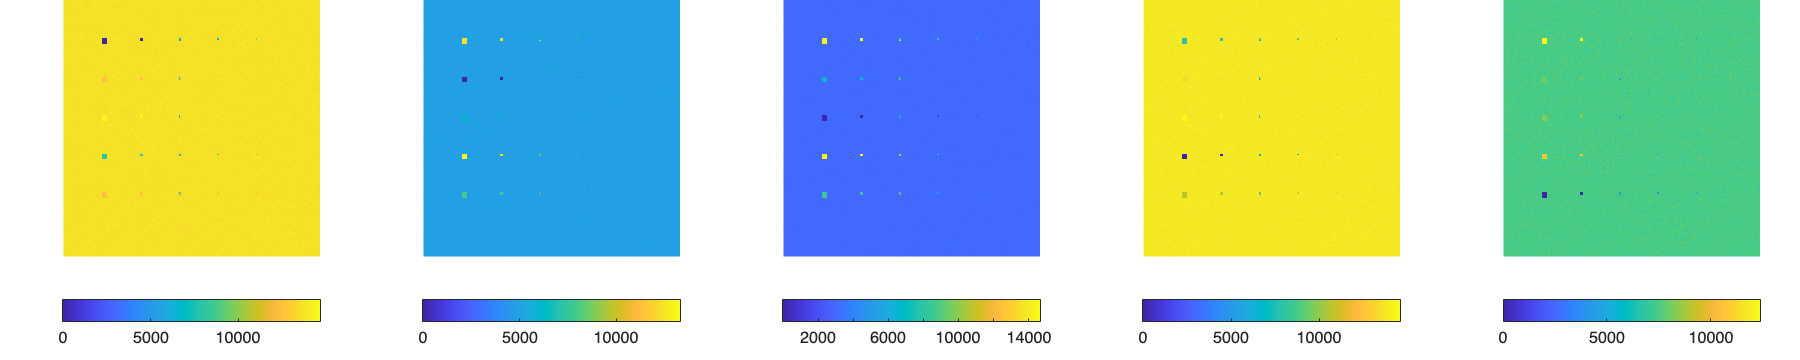

% Orthogonal Projection Divergence (OPD)
figure("Units","pixels","Position",[1,1,1000,200]);
tiledlayout(1,5,"TileSpacing","tight","Padding","tight");
for idx = 1:5
    resultsOPD=OPD(hsi,M(:,idx));
    nexttile,imagesc(resultsOPD),axis off,axis image;
    colorbar southoutside;
end

## Functions for Above Tasks

% Subfunctions
function results = ED(HSI,d)
    [x,y,L] = size(HSI);
    N=x*y;

    r=reshape(HSI,N,L)';

    results = sqrt(sum((r-repmat(d,1,N)).^2,1));
    results = reshape(results,x,y);
end

function results = SAM(HSI,d)
    [x,y,L] = size(HSI);
    N=x*y;

    r=reshape(HSI,N,L);
    r=r./repmat(sqrt(sum(r.^2,2)),1,L);
    d=d/sqrt(sum(d.^2));

    results = r*d;
    results = reshape(results,x,y);
    results(results>1)=1;
    results = acos(results);

end

function results = SID(HSI,d)
    eps = 1e-6;

    [x,y,L] = size(HSI);
    N=x*y;

    r=reshape(HSI,N,L);
    r(r<=0)=eps;
    d(d<=0)=eps;

    r=r./repmat(sum(r,2),1,L);
    d=repmat(d'/sum(d),N,1);

    results=sum(d.*log(r./d),2)+sum(r.*log(d./r),2);
    results = reshape(results,x,y);
end

function results = SID_SAM(HSI,d)
    results = SID(HSI,d).*tan(SAM(HSI,d));
end

function results = OPD(HSI,d)
    [x,y,L] = size(HSI);
    N=x*y;

    r=reshape(HSI,N,L)';
    
    P_U_Per_d=eye(L)-d*pinv(d'*d)*d';

    results = zeros(N,1);

    for idx_pxl = 1:N
        P_U_Per_r=eye(L)-r(:,idx_pxl)*pinv(r(:,idx_pxl)'*r(:,idx_pxl))*r(:,idx_pxl)';
        results(idx_pxl) = d'*P_U_Per_r*d+r(:,idx_pxl)'*P_U_Per_d*r(:,idx_pxl);
    end
    results(results<0)=0;
    results = sqrt(reshape(results,x,y));
end